The following example shows how to design the weights of the radar so that it scans between -30 and 30 degrees yet always keeps a null at 40 degrees. Assume that the radar uses a 10-element ULA that is parallel to the ground and that the known radio interference arrives from 40 degrees azimuth.

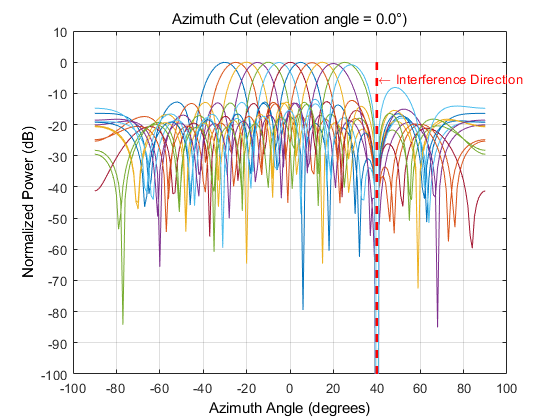

c = 3e8;       % signal propagation speed
fc = 1e9;      % signal carrier frequency
lambda = c/fc; % wavelength

thetaad = -30:5:30;  % look directions
thetaan = 40;        % interference direction

ula = phased.ULA(10,lambda/2);
ula.Element.BackBaffled = true;

% Calculate the steering vector for null directions
wn = steervec(getElementPosition(ula)/lambda,thetaan);

% Calculate the steering vectors for lookout directions
wd = steervec(getElementPosition(ula)/lambda,thetaad);

% Compute the response of desired steering at null direction
rn = wn'*wd/(wn'*wn);

% Sidelobe canceler - remove the response at null direction
w = wd-wn*rn;

% Plot the pattern
pattern(ula,fc,-180:180,0,'PropagationSpeed',c,'Type','powerdb',...
    'CoordinateSystem','rectangular','Weights',w);
hold on;legend off;
plot([40 40],[-100 0],'r--','LineWidth',2)
text(40.5,-5,'\leftarrow Interference Direction','Interpreter','tex',...
    'Color','r','FontSize',10)

This example shows how to construct, visualize and analyze the antenna elements in th Antenna Toolbox.

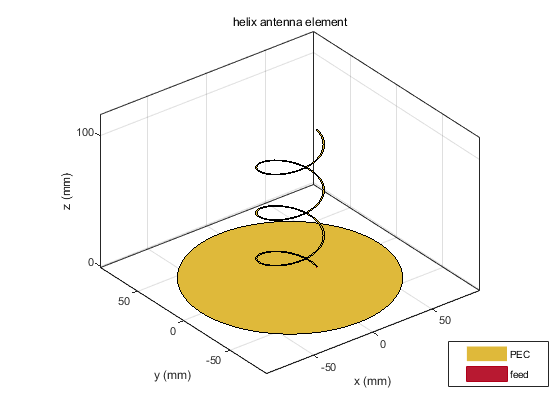

hx = helix;
show(hx)

Discone Antenna for TV Broadcasting System

Rd = 55e-3;   % Radius of disc
Rc1 = 72.1e-3;% Broad Radius of cone
Rc2 = 1.875e-3; % Narrow Radius of cone
Hc = 160e-3; % Vertical height of cone
Fw = 1e-3; % Feed Width
S = 1.75e-3; % Spacing between cone and disc

This above dimensions provided helps to design discone antenna to cover frequencies between 470 and 862MHz, which is the Ultra High Frequency band of TV broadcasting.

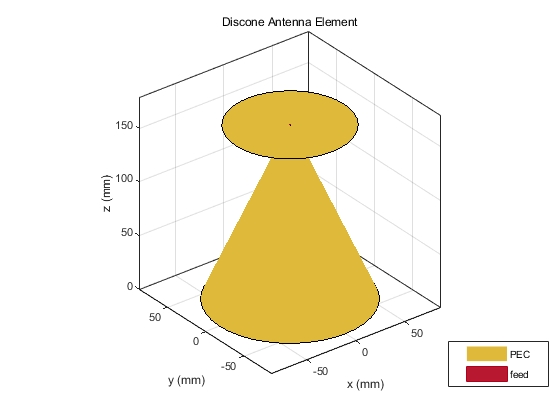

ant = discone;
ant.Height = Hc;
ant.ConeRadii = [Rc2 Rc1];
ant.DiscRadius = Rd;
ant.FeedHeight = S;
ant.FeedWidth = Fw;
figure;
show(ant);
title('Discone Antenna Element')

Linear Arrays

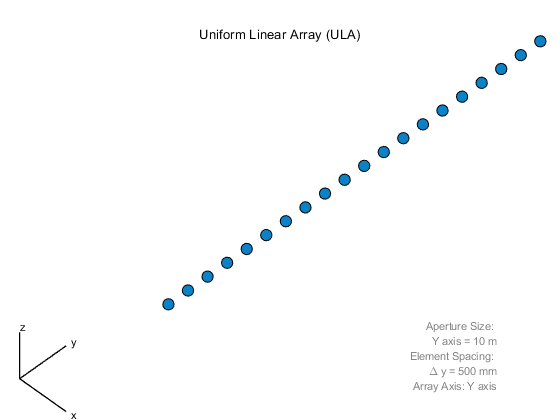

N = 20;
D = 0.5; % Element spacing (m)
ula = phased.ULA(N,D);
viewArray(ula,'Title','Uniform Linear Array (ULA)')
set(gca,'CameraViewAngle',4.4);

Circular Arrays

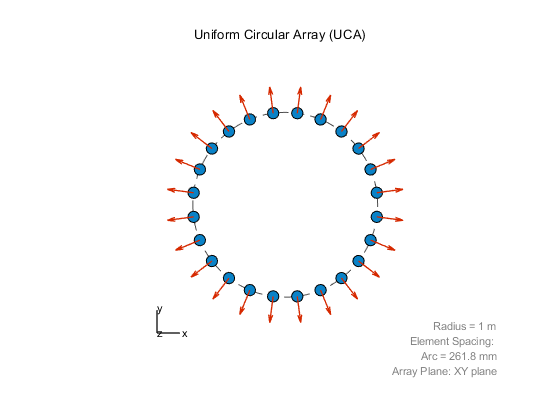

N = 24; % Number of elements
R = 1; % Radius (m)
uca = phased.UCA(N,R);

viewArray(uca,'ShowNormals',true,'Title','Uniform Circular Array (UCA)')
view(0,90)

Multiple circular antenna arrays with the same number of elements and different radii form a concentric circular array.

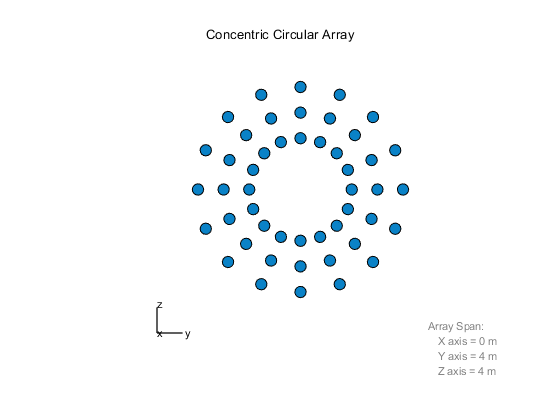

N = 16;                    % Number of elements on each ring
R = [1 1.5 2];             % Radii (m)
azang = (0:N-1)*360/N-180;
pos = [zeros(1,N);cosd(azang);sind(azang)];
elNormal = zeros(2,N);
concentricCircularArray = phased.ConformalArray(...
    'ElementPosition',[R(1)*pos R(2)*pos R(3)*pos],...
    'ElementNormal',[elNormal elNormal elNormal]);

viewArray(concentricCircularArray,'Title','Concentric Circular Array');

Planar antenna arrays can have a uniform grid (or lattice) and different boundary shapes. Next is an example of a Uniform Rectangular Array (URA) with a rectangular grid and rectangular boundary.

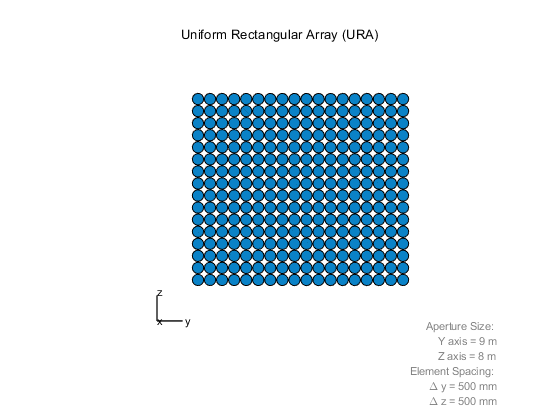

M = 18;   % Number of elements on each row
N = 16;   % Number of elements on each column
dy = 0.5; % Spacing between elements on each row (m)
dz = 0.5; % Spacing between elements on each column (m)
ura = phased.URA([N M],[dz dy]);

viewArray(ura,'Title','Uniform Rectangular Array (URA)');

You can also model a planar antenna array with a circular boundary. The following code starts with a URA and removes elements outside a circle.

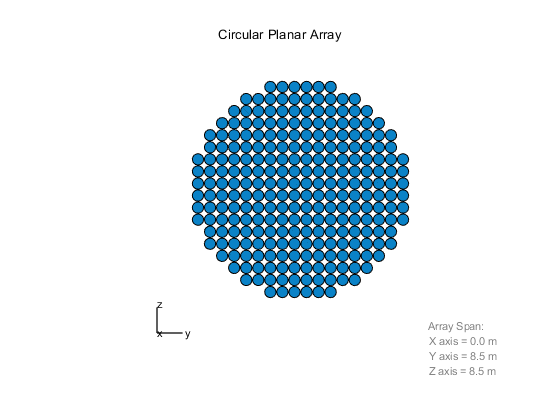

N = 20;   % Number of elements on each row/column of rectangular array
dy = 0.5; % Spacing between elements on each row (m)
dz = 0.5; % Spacing between elements on each column (m)
R = 4.5;  % Radius (m)
refArray = phased.URA(N,[dy,dz]);
pos = getElementPosition(refArray);
elemToRemove = sum(pos.^2)>R^2; 
pos(:,elemToRemove) = []; % Exclude elements outside circle
circularPlanarArray = phased.ConformalArray('ElementPosition',pos,...
                           'ElementNormal',zeros(2,size(pos,2)));

viewArray(circularPlanarArray,'Title','Circular Planar Array');

Next is an example of a planar antenna array with an elliptical boundary.

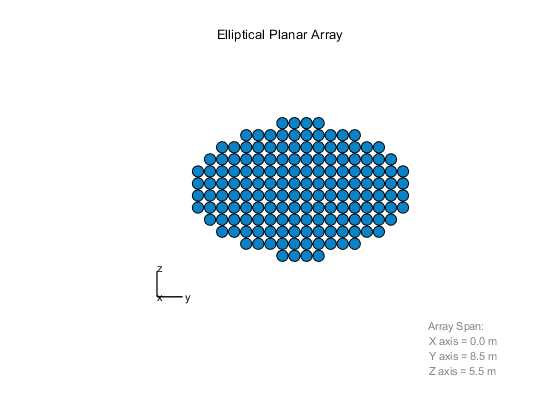

N = 20;   % Number of elements on each row/column of rectangular array
dy = 0.5; % Spacing between elements on each row (m)
dz = 0.5; % Spacing between elements on each column (m)
Ry = 4.5; % Major radius (m)
Rz = 2.8; % Minor radius (m)
refArray = phased.URA(N,[dy,dz]);
pos = getElementPosition(refArray);
elemToRemove = (pos(2,:)/Ry).^2+(pos(3,:)/Rz).^2>1; 
pos(:,elemToRemove) = [];  % Exclude elements outside ellipse
ellipticalPlanarArray = phased.ConformalArray('ElementPosition',pos,...
                           'ElementNormal',zeros(2,size(pos,2)));

viewArray(ellipticalPlanarArray,'Title','Elliptical Planar Array');

The next example is a hexagonal array with a rectangular grid.

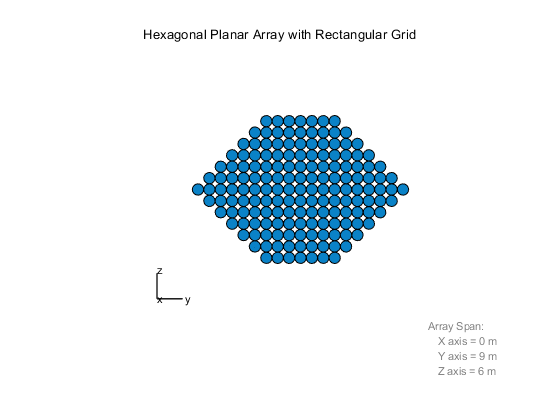

Nmin = 7;      % Number of elements on bottom row
Nmax = 19;     % Number of elements on widest row
dy = 0.5;      % Row spacing
dz = 0.5;      % Column spacing
rows = [Nmin:2:Nmax Nmax-2:-2:Nmin];
N = sum(rows); % Total number of elements
stop = cumsum(rows);
start = stop-rows+1;
pos = zeros(3,N);
count = 0;
for m = Nmin-Nmax:2:Nmax-Nmin
    count = count+1;
    idx = start(count):stop(count);
    pos(2,idx) = (-(rows(count)-1)/2:(rows(count)-1)/2)*dy;
    pos(3,idx) = m/2*dz;
end
hexagonalPlanarArray = phased.ConformalArray('ElementPosition',pos,...
                           'ElementNormal',zeros(2,N));

viewArray(hexagonalPlanarArray,...
    'Title','Hexagonal Planar Array with Rectangular Grid');

Triangular grids provide an efficient spatial sampling and are widely used in practice. Here again, different boundary geometries can be applied. First is a rectangular array with a triangular lattice.

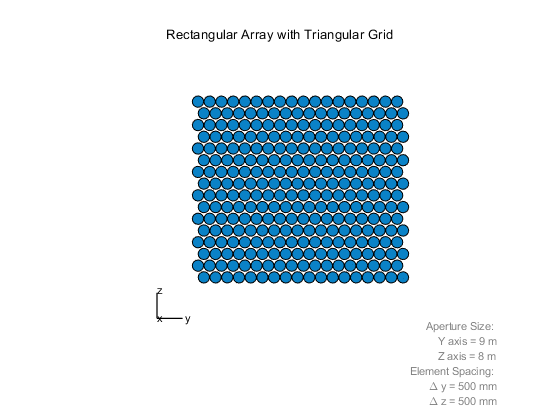

M = 18;   % Number of elements on each row
N = 16;   % Number of elements on each column
dy = 0.5; % Spacing between elements on each row (m)
dz = 0.5; % Spacing between elements on each column (m)
rectArrayTriGrid = phased.URA([N M],[dz dy],'Lattice','Triangular');

viewArray(rectArrayTriGrid,...
    'Title','Rectangular Array with Triangular Grid');

Next is a circular planar antenna array with a triangular lattice.

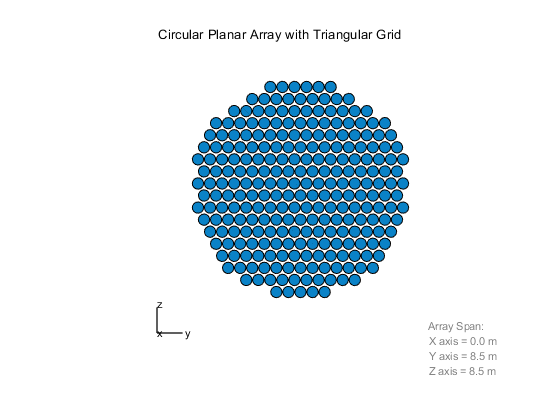

N = 18;   % Number of elements on each row/column of rectangular array
dy = 0.5; % Spacing between elements on each row (m)
dz = 0.5; % Spacing between elements on each column (m)
R = 4.5;  % Radius (m)
refArray = phased.URA(N,[dy,dz],'Lattice','Triangular');
pos = getElementPosition(refArray);
elemToRemove = sum(pos.^2)>R^2; 
pos(:,elemToRemove) = []; % Exclude elements outside circle
circularPlanarArrayTriGrid = phased.ConformalArray(...
    'ElementPosition',pos,'ElementNormal',zeros(2,size(pos,2)));

viewArray(circularPlanarArrayTriGrid,...
    'Title','Circular Planar Array with Triangular Grid');